# Identificazione Primo Giunto da controllore blando.

Modello giunto.

clc;clear all;close all;
set(0, 'defaultFigurePosition',  [ 1, 1, 800, 600]); % figure più grandi

robot=ElasticRoboticSystem('progetto1');
robot.show;

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 840.000000
- torque_2, with maximum limit = 220.000000


Tc = robot.getSamplingPeriod;
robot.initialize;

% utilizzo un controllore "blando" su entrambi i giunti

load 240614_taratura\decentralized_ctrl_j0.mat
decentralized_ctrl.initialize;
decentralized_ctrl.setUMax(robot.getUMax);

## Identificazione

igiunto=1;

#### Portante

omega_portante=1; 
ampiezza_portante=500; % piú di ampiezza id e tale che amp_port+amp_id~70% dei limiti
T_portante=2*pi/omega_portante;
t=(0:Tc:(3.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

#### Segnale eccitante

w0=omega_portante*30; %rad/s
w1=pi/Tc; %rad/s
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');

ampliezza_identificazione=150;  % 1/10-1/2 della coppia massima: a1~=150, a2~=40

% segnale totale segnale eccitante + portante
exciting_signal=zeros(length(t),robot.getInputNumber);
exciting_signal(:,igiunto)=portante+control_action_identificazione*ampliezza_identificazione;


# **Simulo il sistema**

measured_output = robot.readSensorValue();
q0=measured_output(1:2);
Dq0=measured_output(3:4);
DDq0=[0;0];

% initial reference is equal to the inital state of the robot
reference=[q0;Dq0;DDq0];
uff=[0;0];
for idx=1:5e3
    measured_output = robot.readSensorValue();
    joint_torque = decentralized_ctrl.computeControlAction(reference,measured_output,uff);
    % apply torque
    robot.writeActuatorValue(joint_torque);
    % simulate
    robot.simulate();
end

inizio prova


for idx=1:length(t)
    measured_output = robot.readSensorValue();
    uff=exciting_signal(idx,:)';
    joint_torque = decentralized_ctrl.computeControlAction(reference,measured_output,uff);
    % apply torque
    robot.writeActuatorValue(joint_torque);
    % simulate
    robot.simulate();
    control_action(idx,:)=joint_torque;
    measured_signal(idx,:)=measured_output;
    
    
end
joint_position=measured_signal(:,1:2);
joint_velocity=measured_signal(:,3:4);

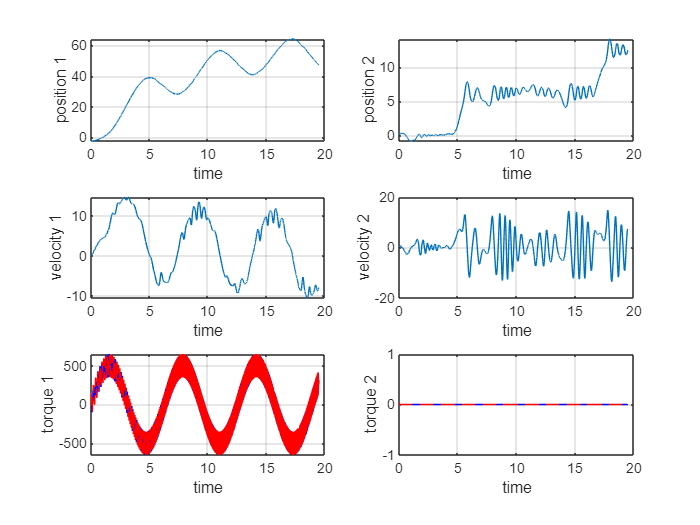

figure(1)
subplot(3,2,1)
plot(t,joint_position(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(3,2,3)
plot(t,joint_velocity(:,1))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(3,2,5)
plot(t,control_action(:,1),'-b',t,exciting_signal(:,1),'--r')
xlabel('time')
ylabel('torque 1')
grid on

subplot(3,2,2)
plot(t,joint_position(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(3,2,4)
plot(t,joint_velocity(:,2))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(3,2,6)
plot(t,control_action(:,2),'-b',t,exciting_signal(:,2),'--r')
xlabel('time')
ylabel('torque 2')
grid on

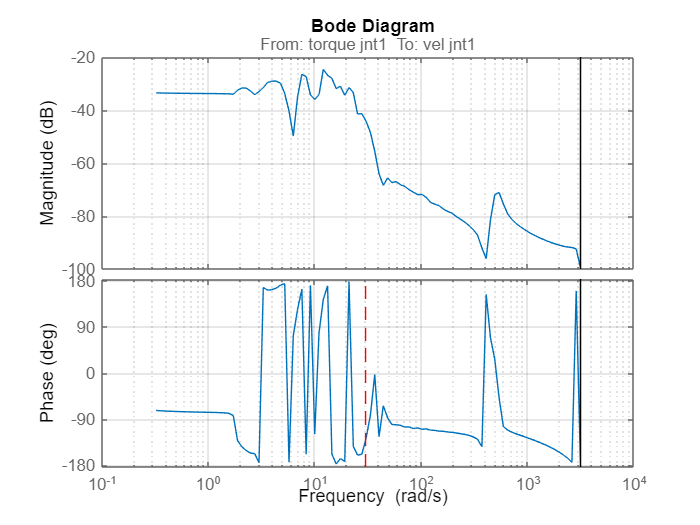

figure
experiment=iddata(joint_velocity(:,igiunto),control_action(:,igiunto),Tc);
experiment.InputName='torque jnt1';
experiment.OutputName='vel jnt1';
experiment_freqresp = spafdr(experiment);

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(experiment_freqresp, bode_opts);
grid on
hold on
hold on
plot(w0*[1 1],ylim,'--r')
hold off
grid on

Definisco i pesi sulla base del diagramma di Bode

peso=ones(length(experiment_freqresp.Frequency),1);
wpeso0=200;
wpeso1=2000;
peso(experiment_freqresp.Frequency<wpeso0)=1e-5;
peso(experiment_freqresp.Frequency>wpeso1)=1e-5;

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo = ssest(experiment_freqresp,3,opts);

modello_discreto = ssest(experiment_freqresp,3,'Ts',Tc,opts);

### Grafico modelli

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h1=bodeplot(experiment_freqresp, bode_opts);
hold on
showConfidence(h1,3) % intervallo confidenza 3*sigma
bode(modello_continuo,modello_discreto, bode_opts)
xlim([w0 w1]) % seleziono banda di interesse
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')

hold off
grid on
xlim([1e-1 1e4])

legend('Identification','Modello continuo','Modello discreto')
% conversione in state-space form del modello continuo trovato
modello_continuo_j1_ss = ss(modello_continuo.A,modello_continuo.B,modello_continuo.C,modello_continuo.D);
modello_continuo_j1_ss.InputName='torque jnt1';
modello_continuo_j1_ss.OutputName='vel jnt1';

# **-------------------------------------------**

# **Validazione**

Cambio portante e segnale eccitante

**Portante**

omega_portante_v=2;
ampiezza_portante_v=250;
T_portante_v=2*pi/omega_portante_v;
t_v=(0:Tc:(3.1*T_portante_v))';
portante_v=ampiezza_portante_v*sin(omega_portante_v*t_v);

**Segnale Eccitante (invertito)**

w0_v=3000; %rad/s
w1_v=omega_portante_v*20; %rad/s
control_action_validazione = chirp(t_v,w0_v/2/pi,t_v(end),w1_v/2/pi, 'logarithmic');
ampliezza_validazione=200;
% segnale totale
exciting_signal_v=zeros(length(t_v),robot.getInputNumber);
exciting_signal_v(:,igiunto)=portante_v+control_action_validazione*ampliezza_validazione;

% COME IN IDENTIFICAZIONE
measured_output_v = robot.readSensorValue();
q0_v=measured_output_v(1:2);
Dq0_v=measured_output_v(3:4);
DDq0_v=[0;0];


% initial reference is equal to the inital state of the robot
reference_v=[q0_v;Dq0_v;DDq0_v];

uff=[0;0];
for idx=1:5e3
    measured_output_v = robot.readSensorValue();
    joint_torque = decentralized_ctrl.computeControlAction(reference_v,measured_output_v,uff); % reference é uguale a quella di identificazione
    % apply torque
    robot.writeActuatorValue(joint_torque);
    % simulate
    robot.simulate();
end

inizio la prova


for idx=1:length(t_v)
    measured_output_v = robot.readSensorValue();
    uff=exciting_signal_v(idx,:)';
    joint_torque = decentralized_ctrl.computeControlAction(reference_v,measured_output_v,uff);
    % apply torque
    robot.writeActuatorValue(joint_torque);
    % simulate
    robot.simulate();
    control_action_val(idx,:)=joint_torque;
    measured_signal_val(idx,:)=measured_output_v;
    
    
end
joint_position_v=measured_signal_val(:,1:2);
joint_velocity_v=measured_signal_val(:,3:4);

figure(1)
subplot(3,2,1)
plot(t_v,joint_position_v(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(3,2,3)
plot(t_v,joint_velocity_v(:,1))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(3,2,5)
plot(t_v,control_action_val(:,1),'-b',t_v,exciting_signal_v(:,1),'--r')
xlabel('time')
ylabel('torque 1')
grid on

subplot(3,2,2)
plot(t_v,joint_position_v(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(3,2,4)
plot(t_v,joint_velocity_v(:,2))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(3,2,6)
plot(t_v,control_action_val(:,2),'-b',t_v,exciting_signal_v(:,2),'--r')
xlabel('time')
ylabel('torque 2')
grid on

### Validazione in frequenza

validation=iddata(joint_velocity_v(:,igiunto),control_action_val(:,igiunto),Tc);
freq_resp_val = spafdr(validation);
figure
bode(freq_resp_val,experiment_freqresp,bode_opts)

Plotto la frequenza di inizio del segnale eccitante

hold on
plot(w0_v*[1 1],ylim,'--r')
hold off
grid on
legend('Validazione','Identificazione')

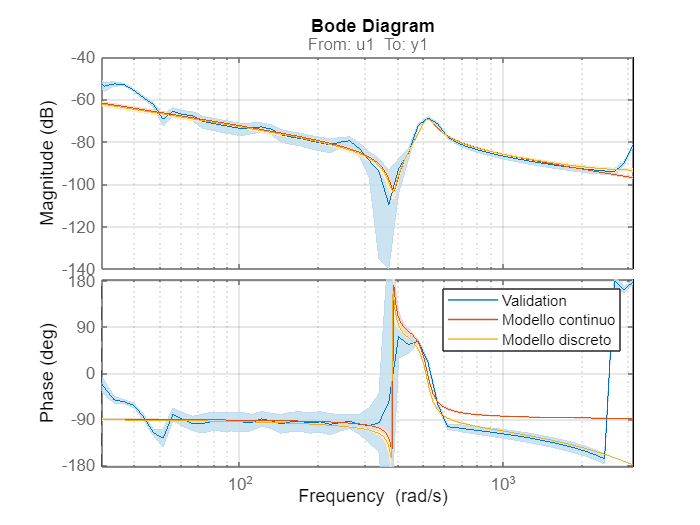

figure
h1=bodeplot(freq_resp_val, bode_opts);
hold on
showConfidence(h1,3)
bode(modello_continuo,modello_discreto, bode_opts)
xlim([w0 w1])
plot(w0*[1 1],ylim,'--r')
hold off
grid on

legend('Validation','Modello continuo','Modello discreto')

% %parte commentata poichè non rilevante ai fini della valutazione

% figure 
% compare(freq_resp_val,modello_discreto) % non devi avere il Corke nel path
% grid on